# Solution of two-variable 2nd order system using Newmark's Method

#### ME6212: Adv FEA

#### Homework 3

Igor Povarich, 02/26/2022

#### Setup

Constants

M = [1 1; 1 2];
C = [1 1; 1 3];
K = C;
F = [1;2];
dt = 0.5;
a = 0.5;
b = 0.5;

K_bar = M+dt*a*C+(dt^2*b/2)*K;

Initialize U's

u_t = [0;0];  % u at time t
du_t = [0;0]; % du/dt at time t
ddu_t = [0;1]; % du^2/dt^2 at time t

% initialize table and assign first row
t = 0;
vars = {'t','u1','u2','du1','du2','ddu1','ddu2'};
tbl = array2table([t u_t' du_t' ddu_t'],'VariableNames',vars)

tbl = 1×7 table
    t    u1    u2    du1    du2    ddu1    ddu2
    _    __    __    ___    ___    ____    ____

    0    0     0      0      0      0       1  


#### Equations


$$\begin{array}{l}
\left\lbrace R_{t+\Delta \;t} \right\rbrace =\frac{\Delta \;t^{2\;} }{2}b\left\lbrace F\right\rbrace +\left\lbrack M\right\rbrack \left(\left\lbrace U_t \right\rbrace +\Delta \;t\left\lbrace \dot{U_t } \right\rbrace +\frac{\Delta \;t^{2\;} }{2}\left(1-b\right)\left\lbrace \ddot{\;U_t \;} \right\rbrace \right)+\;\ldotp \ldotp \ldotp \\
\left\lbrack C\right\rbrack \left(a\Delta \;t\left\lbrace U_t \right\rbrace +\frac{\Delta \;t^{2\;} }{2}\left(2a-b\right)\left\lbrace \dot{\;U_t } \right\rbrace +\frac{\Delta \;t^3 }{2}\left(a-b\right)\left\lbrace \ddot{\;U_t } \right\rbrace \right)
\end{array}$$


Simplified


$$\left\lbrace R_{t+\Delta \;t} \right\rbrace =0\ldotp 0625\left\lbrace F\right\rbrace +M\left(\left\lbrace U_t \right\rbrace +0\ldotp 5\left\lbrace \dot{U_t } \right\rbrace +0\ldotp 0625\left\lbrace \ddot{\;U_t \;} \right\rbrace \right)+C\left(0\ldotp 25\left\lbrace U_t \right\rbrace +0\ldotp 0625\left\lbrace \dot{\;U_t } \right\rbrace \right)$$


Solving for U_t+dt


$$\left\lbrace U_{t+\Delta \;t} \right\rbrace ={\left\lbrack \bar{K} \right\rbrack }^{-1} \left\lbrace R_{t+\Delta \;t} \right\rbrace$$


Simplified 5.151a and b to solve for dU/dt and dU^2/dt^2


$$\left\lbrace \ddot{\;U_{t+\Delta \;t} } \right\rbrace =-\left\lbrace \ddot{\;U_t } \right\rbrace +16\left(\left\lbrace U_{t+\Delta \;t} \right\rbrace -\left\lbrace U_t \right\rbrace -0\ldotp 5\left\lbrace \dot{\;U_t } \right\rbrace \right)$$



$$\left\lbrace \dot{\;U_{t+\Delta \;t} } \right\rbrace =\left\lbrace \dot{\;U_t } \right\rbrace +0\ldotp 25\left(\left\lbrace \ddot{\;U_t } \right\rbrace +\left\lbrace \ddot{\;U_{t+\Delta \;t} } \right\rbrace \right)$$


#### Iterative Calculations

% Loop through time steps (starting at 0.5s to 15s in steps of 0.5s)
for t = 0.5:0.5:15
    
    % R at time t+dt
    R_tdt = (dt^2*b/2)*F+M*(u_t+dt*du_t+(dt^2*(1-b)/2)*ddu_t)+...
        C*(dt*a*u_t+(dt^2*(2*a-b)/2)*du_t+(dt^3*(a-b)/2)*ddu_t);
    % u(t) at time t+dt
    u_tdt = K_bar\R_tdt;
    % du^2/dt^2 at time t+dt
    ddu_tdt = -ddu_t+16*(u_tdt-u_t-0.5*du_t); 
    % du/dt at time t+dt
    du_tdt = du_t+0.25*(ddu_t+ddu_tdt);
    
    % append values to table
    tbl = [tbl;num2cell([t,u_tdt',du_tdt',ddu_tdt'])];
    
    % assign this step as the previous for the next step's calcs
    u_t = u_tdt;
    du_t = du_tdt;
    ddu_t = ddu_tdt;
    
end

% index table to get same ouptut as example
times = [0 0.5:0.5:3 4:10 15];
rows = ismember(tbl.t,times');
tbl(rows,:)

ans = 15×7 table
     t        u1          u2          du1            du2           ddu1          ddu2    
    ___    ________    ________    __________    ___________    __________    ___________

      0           0           0             0              0             0              1
    0.5    0.018315    0.076923       0.07326        0.30769       0.29304        0.23077
      1    0.089844     0.23669       0.21286        0.33136       0.26535       -0.13609
    1.5     0.21884     0.37915       0.30312        0.23851      0.095703       -0.23532
      2     0.37148     0.47113       0.30745        0.12941     -0.078388       -0.20108
    2.5     0.50863     0.51539       0.24116       0.047628      -0.18677       -0.12604
      3     0.60407     

#### Plotting

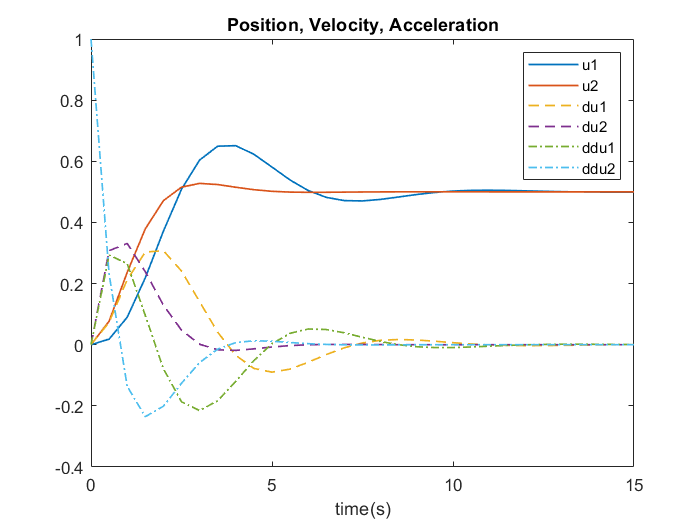

styles = {'-','-','--','--','-.','-.'};
for i=1:width(tbl)-1
   plot(tbl.t,tbl{:,i+1},styles{i},'LineWidth',1); hold on;
end
hold off;
title('Position, Velocity, Acceleration')
xlabel('time(s)')
legend(vars(2:end))